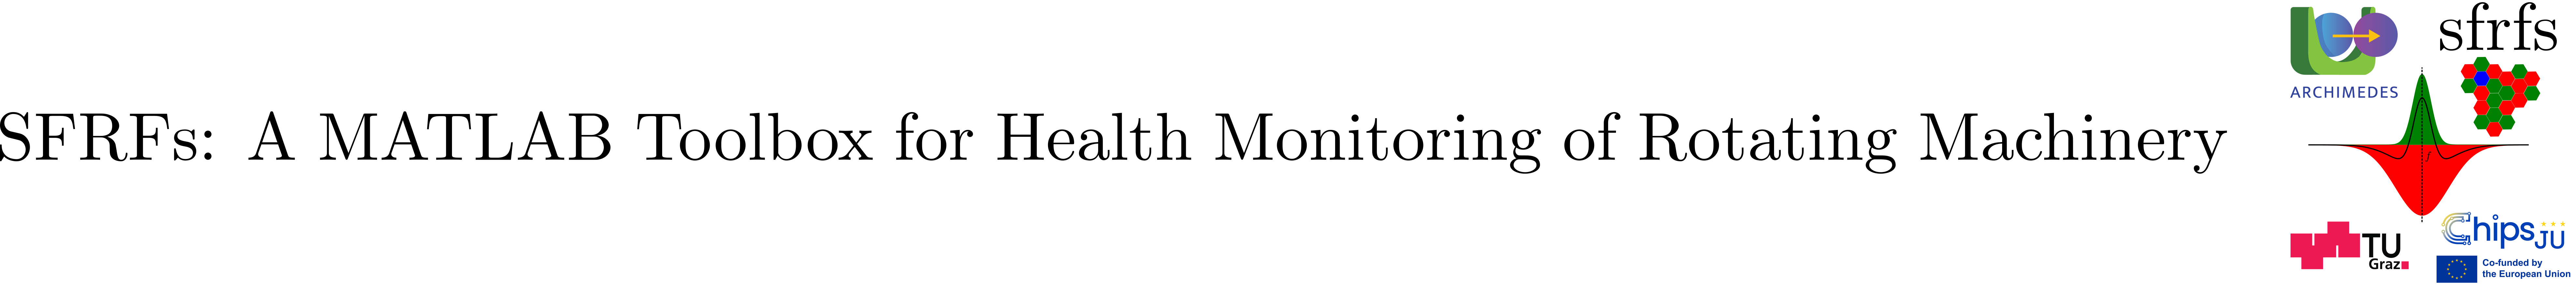

# GaussianMaskParameters

## Summary

GaussianMaskParameters defines the configuration parameters for Gaussian frequency-domain masks used in the SFRFs perceptual pipeline.

## Description

GaussianMaskParameters encapsulates the parameterization of Gaussian frequency-domain gain masks independently of their evaluation. It specifies how the width of the Gaussian profile is derived from a frequency band via a sigma rule and whether the resulting mask is normalized.

This class is intended to be used with `FrequencyMask.evaluate`, providing a clean separation between mask configuration and mask computation. The legacy method `FrequencyMask.gaussian` is retained for backward compatibility, while GaussianMaskParameters enables a unified, extensible parameter-object-based interface consistent with other mask types.

### Properties

### Notes

- This class does not perform mask evaluation itself.

- GaussianMaskParameters is consumed by `FrequencyMask.evaluate` to construct Gaussian masks.

- The legacy method `FrequencyMask.gaussian` remains available for backward compatibility and direct use.

### See also

[FrequencyMask](matlab:open('./FrequencyMask.mlx')), [SuperGaussianMaskParameters](matlab:open('./SuperGaussianMaskParameters.mlx')), [MaskParameters](matlab:open('./MaskParameters.mlx'))

## Example

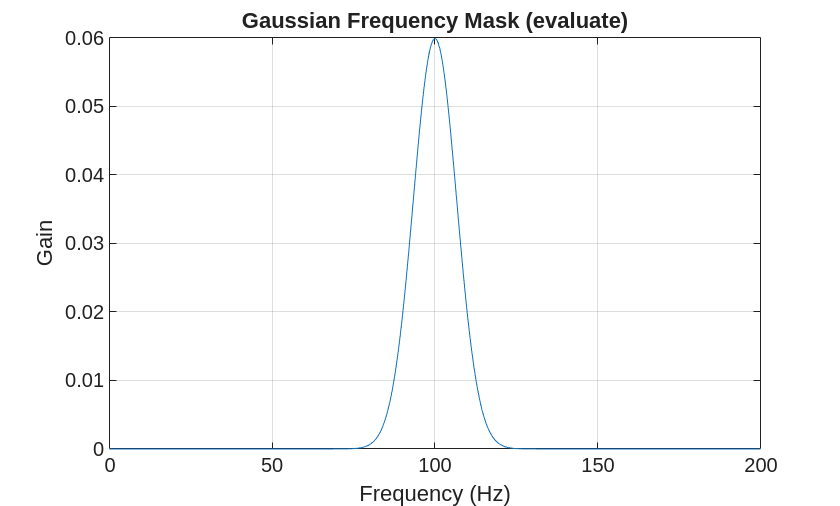

% Frequency axis
f = linspace(0, 200, 2048).';

% Frequency band
band = [80 120];

% Define Gaussian mask parameters
params = GaussianMaskParameters( ...
    sigmaRule = 3, ...
    normalize = true);

% Evaluate Gaussian mask via unified interface
G = FrequencyMask.evaluate(f, band, params);

plot(f, G);
grid on;
xlabel("Frequency (Hz)");
ylabel("Gain");
title("Gaussian Frequency Mask (evaluate)");

## API documentation

### MATLAB help

help GaussianMaskParameters

  GaussianMaskParameters
 
  Parameter container for Gaussian mask profiles.
 
  The associated (continuous) Gaussian mask profile is:
 
    G(f) = exp( -1/2 * ((f - f_c) / sigma)^2 )
 
  where:
    - f_c     is the mask center frequency (defined externally),
    - sigma   is derived from the reference bandwidth and sigmaRule as
              sigma = bandwidth / (2 * sigmaRule).
 
  This class stores parameters in the inherited struct dictionary while
  providing a stable, explicit ontology for the Gaussian family.
 
  Expected parameter keys (conventions are local to this toolbox):
    - bandwidth   : positive scalar, in Hz (reference width)
    - sigmaRule   : positive scalar, dimensionless
    - normalize   : logical scalar (optional)
 
  Notes:
    - Mask evaluation and discretization are handled elsewhere
      (e.g., FrequencyMask.gaussian).

    Documentation for GaussianMaskParameters



## Source code

The source of the class can be found in [GaussianMaskParameters](matlab:open('../../GaussianMaskParameters.m')).

## Test

Unit testing for the class is implemented in TestGaussianMaskParameters.

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestGaussianMaskParameters');

Running TestGaussianMaskParameters
....
Done TestGaussianMaskParameters
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestGaussianMaskParameters/testDefaultParameters                                 | Passed
TestGaussianMaskParameters/testCustomParameters                                  | Passed
TestGaussianMaskParameters/testGetReferenceBandwidth                             | Passed
TestGaussianMaskParameters/testValidationErrors                                  | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).